%% Non-Convex Optimization using Genetic Algorithm (GA)
%  Minimizes a non-convex function with multiple local minima.
%
%  Example objective (2D Rastrigin function – highly non-convex):
%    f(x1,x2) = 20 + x1^2 - 10*cos(2*pi*x1) + x2^2 - 10*cos(2*pi*x2)
%  Global minimum: f(0,0) = 0
%
%  GA Steps per generation:
%    1. Initialise random population
%    2. Evaluate fitness
%    3. Selection  (tournament)
%    4. Crossover  (single-point / arithmetic)
%    5. Mutation   (Gaussian)
%    6. Elitism    (keep best individual)
%
%  Author : Generated Example
%  Toolbox: None required – pure MATLAB implementation

clear; clc; close all;

%% ── 1. Objective Function ────────────────────────────────────────────────

% Rastrigin function (non-convex, many local minima)
f = @(x) 20 + x(1)^2 - 10*cos(2*pi*x(1)) ...
            + x(2)^2 - 10*cos(2*pi*x(2));

n_vars = 2;                        % Number of decision variables
lb     = [-5.12, -5.12];           % Lower bounds
ub     = [ 5.12,  5.12];           % Upper bounds

%% ── 2. GA Parameters ─────────────────────────────────────────────────────

pop_size      = 100;     % Population size
max_gen       = 200;     % Maximum generations
p_crossover   = 0.8;     % Crossover probability
p_mutation    = 0.05;    % Mutation probability per gene
mutation_std  = 0.5;     % Std dev of Gaussian mutation noise
tournament_k  = 3;       % Tournament selection size
elitism_n     = 2;       % Number of elite individuals carried forward
tol           = 1e-8;    % Convergence tolerance (best fitness change)
stall_limit   = 50;      % Stop if best fitness unchanged for this many gens

%% ── 3. Initialise Population ─────────────────────────────────────────────

% Each row = one individual [x1, x2, ..., xn]
pop = lb + rand(pop_size, n_vars) .* (ub - lb);

best_fitness_history = zeros(max_gen, 1);
mean_fitness_history = zeros(max_gen, 1);
best_individual      = pop(1, :);
best_fitness         = Inf;
stall_count          = 0;

fprintf('\n=================================================================\n');

fprintf('  Non-Convex Optimization  –  Genetic Algorithm\n');

  Non-Convex Optimization  –  Genetic Algorithm


fprintf('  Function : Rastrigin 2D   |  Global min f(0,0) = 0\n');

  Function : Rastrigin 2D   |  Global min f(0,0) = 0


fprintf('=================================================================\n');

fprintf('  Gen  |  Best f(x)    |  Mean f(x)    |  Best x1      |  Best x2\n');

  Gen  |  Best f(x)    |  Mean f(x)    |  Best x1      |  Best x2


fprintf('-----------------------------------------------------------------\n');

-----------------------------------------------------------------



%% ── 4. Main GA Loop ──────────────────────────────────────────────────────

for gen = 1:max_gen

    %% 4a. Evaluate fitness
    fitness = zeros(pop_size, 1);
    for i = 1:pop_size
        fitness(i) = f(pop(i, :));
    end

    %% 4b. Track best individual (elitism seed)
    [gen_best_fit, idx] = min(fitness);
    if gen_best_fit < best_fitness
        best_fitness    = gen_best_fit;
        best_individual = pop(idx, :);
        stall_count     = 0;
    else
        stall_count = stall_count + 1;
    end

    best_fitness_history(gen) = best_fitness;
    mean_fitness_history(gen) = mean(fitness);

    % ── Print progress ────────────────────────────────────────────────
    if gen <= 5 || mod(gen, 25) == 0
        fprintf('  %4d | %13.6f | %13.6f | %13.6f | %13.6f\n', ...
            gen, best_fitness, mean(fitness), ...
            best_individual(1), best_individual(2));
    end

    % ── Convergence checks ────────────────────────────────────────────
    if best_fitness < tol
        fprintf('\n  ✓ Global minimum reached at generation %d\n', gen);
        best_fitness_history = best_fitness_history(1:gen);
        mean_fitness_history = mean_fitness_history(1:gen);
        break
    end
    if stall_count >= stall_limit
        fprintf('\n  ✓ Stall limit reached at generation %d  (no improvement for %d gens)\n', gen, stall_limit);
        best_fitness_history = best_fitness_history(1:gen);
        mean_fitness_history = mean_fitness_history(1:gen);
        break
    end

    %% 4c. Sort population by fitness for elitism
    [fitness_sorted, sort_idx] = sort(fitness);
    pop_sorted = pop(sort_idx, :);
    elites     = pop_sorted(1:elitism_n, :);   % Keep top individuals

    %% 4d. Tournament Selection
    selected = zeros(pop_size, n_vars);
    for i = 1:pop_size
        candidates = randperm(pop_size, tournament_k);
        [~, win]   = min(fitness(candidates));
        selected(i, :) = pop(candidates(win), :);
    end

    %% 4e. Crossover (single-point + arithmetic blend)
    offspring = selected;
    for i = 1:2:pop_size - 1
        if rand < p_crossover
            % Arithmetic (blend) crossover
            alpha       = rand;
            offspring(i,   :) = alpha * selected(i, :) + (1-alpha) * selected(i+1, :);
            offspring(i+1, :) = alpha * selected(i+1,:) + (1-alpha) * selected(i,   :);
        end
    end

    %% 4f. Gaussian Mutation
    mutation_mask = rand(pop_size, n_vars) < p_mutation;
    noise         = mutation_std * randn(pop_size, n_vars);
    offspring     = offspring + mutation_mask .* noise;

    % Enforce bounds (clip)
    offspring = max(offspring, lb);
    offspring = min(offspring, ub);

    %% 4g. Elitism – replace worst individuals with elites
    offspring(end-elitism_n+1:end, :) = elites;

    pop = offspring;
end

     1 |      7.847449 |     36.185330 |     -0.984318 |     -1.865809
     2 |      1.409788 |     25.709706 |     -0.035569 |      0.966056
     3 |      1.219707 |     20.567685 |      0.028422 |      0.073746
     4 |      1.219707 |     18.591303 |      0.028422 |      0.073746
     5 |      0.311568 |     14.748765 |      0.010816 |      0.038216



  ✓ Global minimum reached at generation 22



%% ── 5. Results ───────────────────────────────────────────────────────────

fprintf('\n=================================================================\n');

fprintf('  Final Results\n');

  Final Results


fprintf('=================================================================\n');

fprintf('  Optimal x1     = %12.8f\n', best_individual(1));

  Optimal x1     =  -0.00000154


fprintf('  Optimal x2     = %12.8f\n', best_individual(2));

  Optimal x2     =  -0.00000434


fprintf('  Optimal f(x*)  = %12.8f\n', best_fitness);

  Optimal f(x*)  =   0.00000000


fprintf('  Known global   =  0.00000000  at (0, 0)\n');

  Known global   =  0.00000000  at (0, 0)


fprintf('  Error          = %12.2e\n',  norm(best_individual));

  Error          =     4.61e-06


fprintf('=================================================================\n\n');

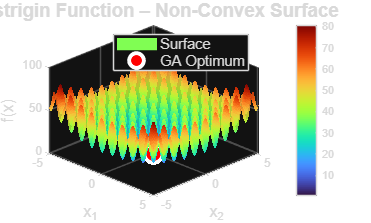


%% ── 6. Visualisation ─────────────────────────────────────────────────────

% 6a. 3-D surface of the Rastrigin function
figure('Name','Rastrigin Surface','NumberTitle','off','Color','w');
[X1, X2] = meshgrid(linspace(-5.12, 5.12, 300));
F = 20 + X1.^2 - 10*cos(2*pi*X1) + X2.^2 - 10*cos(2*pi*X2);

surf(X1, X2, F, 'EdgeColor','none', 'FaceAlpha', 0.85);
colormap(turbo); colorbar;
hold on;
plot3(best_individual(1), best_individual(2), best_fitness+0.5, ...
      'wo', 'MarkerSize', 14, 'LineWidth', 3, 'MarkerFaceColor','r');
xlabel('x_1','FontSize',12); ylabel('x_2','FontSize',12); zlabel('f(x)','FontSize',12);
title('Rastrigin Function – Non-Convex Surface','FontSize',14,'FontWeight','bold');
legend({'Surface','GA Optimum'},'FontSize',11,'Location','northeast');
view(45, 35); hold off;

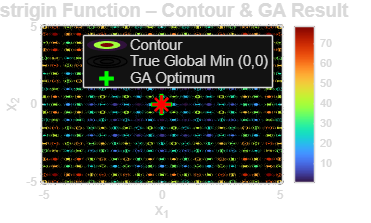


% 6b. Contour plot with found optimum
figure('Name','Contour + Optimum','NumberTitle','off','Color','w');
contourf(X1, X2, F, 40, 'LineColor','none'); colormap(turbo); colorbar;
hold on;
contour(X1, X2, F, 20, 'k', 'LineWidth', 0.4);
plot(0, 0, 'g+', 'MarkerSize', 16, 'LineWidth', 3);          % True global min
plot(best_individual(1), best_individual(2), 'r*', ...
     'MarkerSize', 14, 'LineWidth', 2);
xlabel('x_1','FontSize',12); ylabel('x_2','FontSize',12);
title('Rastrigin Function – Contour & GA Result','FontSize',14,'FontWeight','bold');
legend({'Contour','True Global Min (0,0)','GA Optimum'},'FontSize',11,'Location','northeast');
hold off;

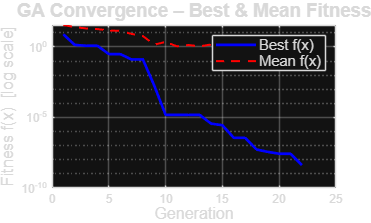


% 6c. Convergence: best and mean fitness per generation
figure('Name','GA Convergence','NumberTitle','off','Color','w');
gens = 1:length(best_fitness_history);
semilogy(gens, best_fitness_history, 'b-',  'LineWidth', 2, 'DisplayName','Best f(x)');
hold on;
semilogy(gens, mean_fitness_history, 'r--', 'LineWidth', 1.5, 'DisplayName','Mean f(x)');
xlabel('Generation','FontSize',12);
ylabel('Fitness f(x)  [log scale]','FontSize',12);
title('GA Convergence – Best & Mean Fitness','FontSize',14,'FontWeight','bold');
legend('FontSize',11); grid on; box on; hold off;


%% ── 7. Sensitivity: run GA multiple times to show stochastic behaviour ───

n_runs    = 10;
run_best  = zeros(n_runs, 1);
run_soln  = zeros(n_runs, n_vars);

fprintf('  Running GA %d independent times to show stochastic spread...\n\n', n_runs);

  Running GA 10 independent times to show stochastic spread...



fprintf('  Run |  Best f(x*)   |  x1*          |  x2*\n');

  Run |  Best f(x*)   |  x1*          |  x2*


fprintf('  --------------------------------------------------\n');

  --------------------------------------------------



for r = 1:n_runs
    pop_r = lb + rand(pop_size, n_vars) .* (ub - lb);
    bf_r  = Inf;
    bi_r  = pop_r(1,:);

    for g = 1:max_gen
        fit_r = arrayfun(@(i) f(pop_r(i,:)), 1:pop_size)';
        [gbf, gidx] = min(fit_r);
        if gbf < bf_r; bf_r = gbf; bi_r = pop_r(gidx,:); end

        % Selection
        sel_r = zeros(pop_size, n_vars);
        for i = 1:pop_size
            cands = randperm(pop_size, tournament_k);
            [~,w] = min(fit_r(cands));
            sel_r(i,:) = pop_r(cands(w),:);
        end
        % Crossover
        off_r = sel_r;
        for i = 1:2:pop_size-1
            if rand < p_crossover
                a = rand;
                off_r(i,:)   = a*sel_r(i,:)   + (1-a)*sel_r(i+1,:);
                off_r(i+1,:) = a*sel_r(i+1,:) + (1-a)*sel_r(i,:);
            end
        end
        % Mutation
        mm = rand(pop_size,n_vars) < p_mutation;
        off_r = off_r + mm.*mutation_std.*randn(pop_size,n_vars);
        off_r = max(min(off_r,ub),lb);
        % Elitism
        [~,si] = sort(fit_r);
        off_r(end,:) = pop_r(si(1),:);
        pop_r = off_r;

        if bf_r < tol; break; end
    end

    run_best(r)   = bf_r;
    run_soln(r,:) = bi_r;
    fprintf('  %3d | %13.6f | %13.6f | %13.6f\n', r, bf_r, bi_r(1), bi_r(2));
end

    1 |      0.000000 |     -0.000040 |      0.000009
    2 |      0.000002 |     -0.000041 |     -0.000079
    3 |      0.000311 |     -0.001253 |      0.000000
    4 |      0.000141 |     -0.000842 |      0.000000
    5 |      0.000000 |      0.000004 |     -0.000002
    6 |      0.000009 |     -0.000212 |      0.000007
    7 |      0.000000 |      0.000003 |      0.000008
    8 |      0.000000 |     -0.000000 |      0.000000
    9 |      0.000000 |      0.000002 |     -0.000000
   10 |      0.000007 |      0.000000 |     -0.000194



fprintf('\n  Multi-run summary across %d runs:\n', n_runs);


  Multi-run summary across 10 runs:


fprintf('  Mean best f* = %.6f,  Std = %.6f\n', mean(run_best), std(run_best));

  Mean best f* = 0.000047,  Std = 0.000103


fprintf('  Best overall = %.6f\n\n', min(run_best));

  Best overall = 0.000000

